Create Enviroment Interafce

%env = rlPredefinedEnv("CartPole-Discrete");
%obsInfo = getObservationInfo(env);
%actInfo = getActionInfo(env);

Create customized Enviroment Interafce

obsInfo = rlNumericSpec([4 1]);
obsInfo.Name = "CartPole States";
obsInfo.Description = 'x, dx, theta, dtheta';
actInfo = rlFiniteSetSpec([-10 10]);
actInfo.Name = "CartPole Action";
%type resetFunction.m
%type stepFunction.m
resetFnc = @resetFunction

resetFnc = function_handle with value:
    @resetFunction


stepFnc = @stepFunction

stepFnc = function_handle with value:
    @stepFunction


env = rlFunctionEnv(obsInfo, actInfo, stepFnc, resetFnc);


Create DQN Agent

net = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(length(actInfo.Elements))
    ];
criticNet = dlnetwork(net);
%deepNetworkDesigner(net)

critic = rlVectorQValueFunction(net, obsInfo, actInfo);
criticOpts = rlOptimizerOptions(...
    LearnRate=1e-3,...
    GradientThreshold=1);
agentOpts = rlDQNAgentOptions(...
    UseDoubleDQN=false,...
    CriticOptimizerOptions=criticOpts,...
    TargetSmoothFactor=1,...
    TargetUpdateFrequency=4,...
    ExperienceBufferLength=1e5,...
    MiniBatchSize=128);

agent = rlDQNAgent(critic, agentOpts);

Train Agent

trainOpts = rlTrainingOptions(...
    MaxEpisodes=1000, ...
    MaxStepsPerEpisode=500, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward");
%plot(env);
info = train(agent, env, trainOpts)

info =   rlTrainingResult with properties:

           EpisodeIndex: [131×1 double]
          EpisodeReward: [131×1 double]
           EpisodeSteps: [131×1 double]
          AverageReward: [131×1 double]
        TotalAgentSteps: [131×1 double]
           AverageSteps: [131×1 double]
              EpisodeQ0: [131×1 double]
         SimulationInfo: [131×1 struct]
    EvaluationStatistic: [131×1 double]
        TrainingOptions: [1×1 rl.option.rlTrainingOptions]


Simulate DQN Agent

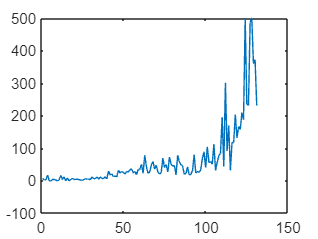

plot(info.EpisodeReward)

simOptions = rlSimulationOptions(MaxSteps=500);
simout = sim(env,agent,simOptions);

Reset e Step Function for Enviroment

function [InitialObservation, Info] = resetFunction()

T0 = 2 * 0.05 * rand() - 0.05;
Td0 = 0;
X0 = 0;
Xd0 = 0;

Info = [X0;Xd0;T0;Td0];
InitialObservation = Info;

end

function [NextObs,Reward,IsDone,NextState] = stepFunction(Action,State)

% Define the environment constants.

% Acceleration due to gravity in m/s^2
Gravity = 9.8;
% Mass of the cart
CartMass = 1.0;
% Mass of the pole
PoleMass = 0.1;
% Half the length of the pole
HalfPoleLength = 0.5;
% Max force the input can apply
MaxForce = 10;
% Sample time
Ts = 0.02;
% Pole angle at which to fail the episode
AngleThreshold = 12 * pi/180;
% Cart distance at which to fail the episode
DisplacementThreshold = 2.4;
% Reward each time step the cart-pole is balanced
RewardForNotFalling = 1;
% Penalty when the cart-pole fails to balance
PenaltyForFalling = -10;

% Check if the given action is valid.
%if ~ismember(Action,[-MaxForce MaxForce])
%    error('Action must be %g for going left and %g for going right.',...
%        -MaxForce,MaxForce);
%end
Force = Action;

% Unpack the state vector from the logged signals.
XDot = State(2);
Theta = State(3);
ThetaDot = State(4);

% Cache to avoid recomputation.
CosTheta = cos(Theta);
SinTheta = sin(Theta);
SystemMass = CartMass + PoleMass;
%legge del moto di Newton (F=ma)
temp = (Force + PoleMass*HalfPoleLength*ThetaDot*ThetaDot*SinTheta)/SystemMass;

% Apply motion equations.
%accelerazione angolare del pendolo
ThetaDotDot = (Gravity*SinTheta - CosTheta*temp) / ...
    (HalfPoleLength*(4.0/3.0 - PoleMass*CosTheta*CosTheta/SystemMass));
%accelerazione del carrello
XDotDot  = temp - PoleMass*HalfPoleLength*ThetaDotDot*CosTheta/SystemMass;

% Perform Euler integration to calculate next state.
NextState = State + Ts.*[XDot;XDotDot;ThetaDot;ThetaDotDot];

% Copy next state to next observation.
NextObs = NextState;

% Check terminal condition.
X = NextObs(1);
Theta = NextObs(3);
IsDone = abs(X) > DisplacementThreshold || abs(Theta) > AngleThreshold;

% Calculate reward.
if ~IsDone
    Reward = RewardForNotFalling;
else
    Reward = PenaltyForFalling;
end

end